## ELEC5305 Audio Processing Report Two

# Noise Reduction and Speech Preservation in STFT Spectral Subtraction

Author: Chenxin Zhang | SID: 540881826

Project repository: https://github.com/Chenx104/elec5305-speech-enhancement

Date: 29 October 2026

### 1. Objective

Report 1 used known clean speech and noise to construct an oracle mask. This report estimates noise from the noisy recording and compares two estimators using the same spectral-subtraction rule. It measures how much noise is reduced and how much speech energy is lost. Tests use 0, 5 and 10 dB input signal-to-noise ratios (SNRs). The main example is followed by tests with three additional speakers, car-idle noise, rain and three white-noise sequences. It also tests whether SI-SDR and STOI rank the methods consistently. These comparisons provide a classical enhancement baseline for the final project.

### 2. Background

The short-time Fourier transform (STFT) divides speech into short, overlapping frames so that its changing frequency content can be analysed. Spectral subtraction estimates the noise power in each frequency bin and subtracts it from the noisy power spectrum [1]. A gain then scales the noisy STFT. Inverse STFT and weighted overlap-add reconstruct the signal. A spectral floor limits attenuation, although musical-noise artefacts can still occur.

This report compares two noise power spectral density (PSD) estimators. The percentile method selects low-energy frames from the full recording and averages their power spectra. It assumes that these frames contain little speech. The second method uses a simplified voice activity detector (VAD) with two thresholds and a tracked noise floor. It updates the PSD during frames classified as noise. The detector uses unweighted spectral frame levels.

Output SNR measures the error relative to clean speech at its original level. Scale-invariant signal-to-distortion ratio (SI-SDR) allows an overall level change [2]. Short-time objective intelligibility (STOI) predicts intelligibility using clean speech as a reference [3], [4]. Speaker identity requires a separate evaluation.

### 3. Methodology and Implementation

Figure 1 shows the pipeline. The main inputs are the Open Speech Repository recording OSR_us_000_0010_8k.wav, saved as clean_speech.wav [5], and the course-provided car_idle.mp3 recording, saved as car_idle_noise.mp3. They are converted to mono at 8 kHz and trimmed to 7.008 s (56,064 samples). After mean removal, speech is peak-normalized and noise is scaled for 0, 5 and 10 dB mixtures. Fixed-seed white noise provides a second condition.

The STFT uses a 256-sample Hann window, a 64-sample hop and a 512-point fast Fourier transform (FFT). Padding and weighted overlap-add preserve the full signal length. Noise estimation uses only frames without padding.

The percentile method selects frames at or below the 20th percentile of noisy frame levels, then averages their power spectra. The VAD initializes from 32 complete frames (a nominal 0.25 s setting), assumed to contain mainly noise, and then updates its estimate using noise-labelled frames.

After initialization, the VAD labels a frame as speech when its level exceeds 3.5 times the tracked noise floor, and as noise when its level falls below 1.5 times the floor. Between these thresholds, it keeps the previous decision. The floor rises with a 10 s time constant and falls with a 0.04 s time constant. After initialization, noise-labelled frames update the PSD with a 0.20 s smoothing constant.

Both estimators use alpha = 1.5 to control over-subtraction and beta = 0.02 as the power-gain floor. In Equation (1), $P_y = |Y|²$ is the noisy power spectrum and $P_d$ is its noise estimate. The indices k and m identify frequency bins and frames. The numerical safeguard delta is MATLAB realmin, the smallest positive normalized double. For an exactly zero-power bin, the code sets G to sqrt(beta); its output is still zero.


$$\[G(k,m)=\sqrt{\frac{\max(P_y(k,m)-\alpha P_d(k,m),\,\beta P_y(k,m))}{\max(P_y(k,m),\delta)}},\quad P_y>0,\quad Z=GY.\qquad(1)\]$$


The amplitude-gain floor is sqrt(beta), approximately 0.1414 (−16.99 dB). This limits the gain, not the absolute output amplitude. The true-PSD reference uses the average exact-noise power spectrum with the same subtraction rule. The oracle Wiener-style reference uses $G_o = 0.05 + 0.95|X|²/max(|X|² + |D|², delta)$, where X and D are the clean-speech and exact-noise STFTs. It also changes the gain rule and uses clean speech. Neither reference establishes a general performance bound.

Evaluation uses signals before playback scaling. Applying each fixed gain separately to X and D separates speech distortion from residual noise. The same methods are tested on 5 s recordings from three LibriSpeech speakers [6], using unchanged parameters. This additional set uses car-idle noise, an ESC-50 rain recording [7] and generated white noise.

The gain is estimated from noisy speech and then held fixed. Applying it separately to clean speech and exact noise gives the processed speech component s_x and residual noise d_n. Their sum matches the enhanced output. Noise attenuation is 10 $log10(||d||²/||d_n||²)$, speech retained is $100||s_x||²/||x||²$, and distortion SNR is 10 $log10(||x||²/||s_x - x||²$).

Output SNR is $10 log10(||x||^2/||z-x||^2)$, where x is clean speech and z is the output. SI-SDR uses zero-mean signals $x_c$ and $z_c$. With $a = <x_c,z_c>/||x_c||^2$, SI-SDR is $10 log10(||a x_c||^2/||z_c-a x_c||^2)$.

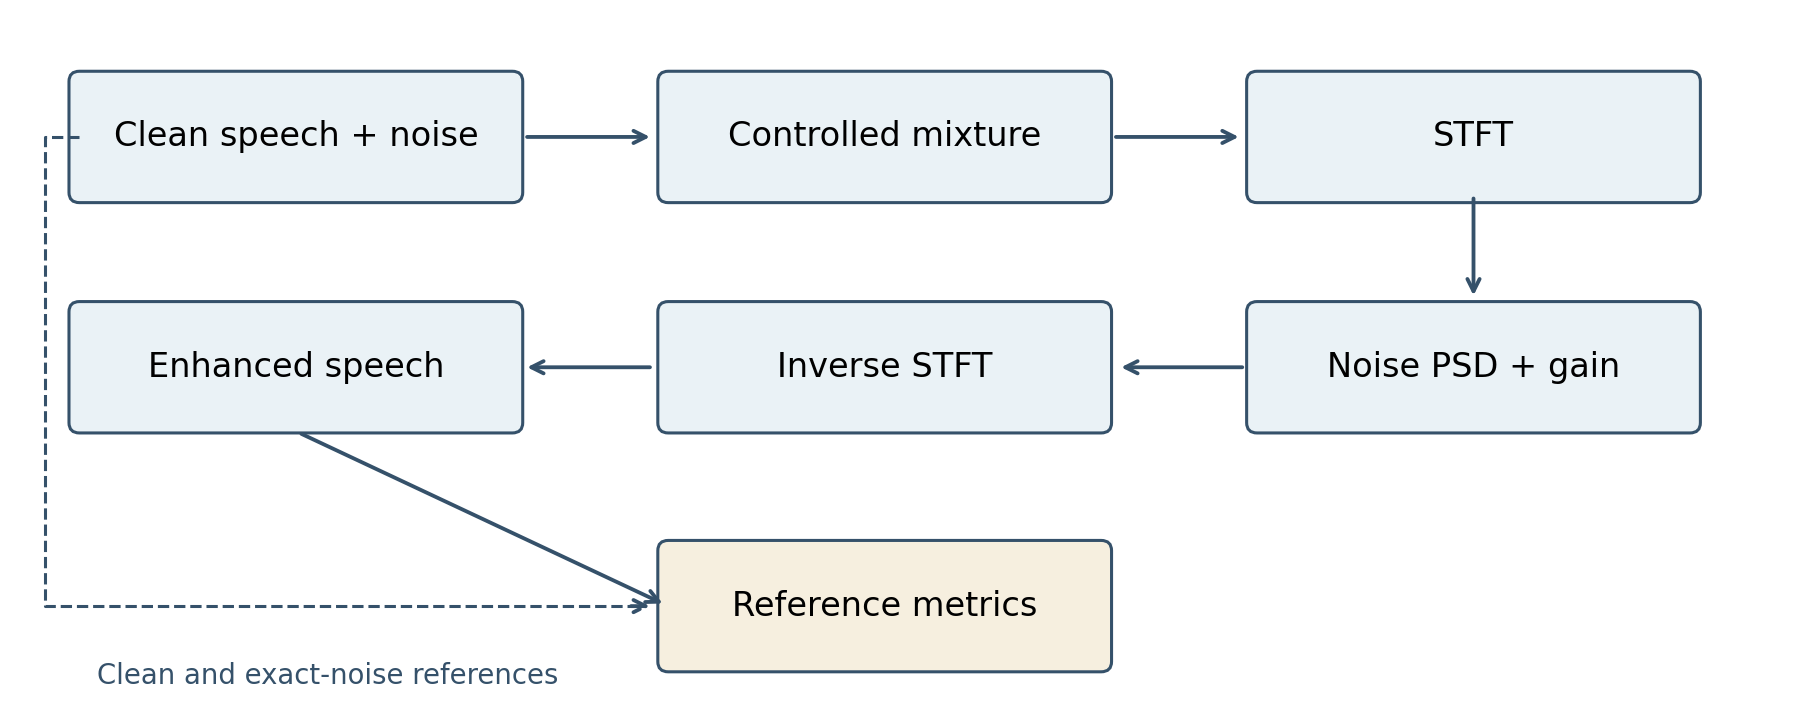

Figure 1. Practical enhancement and reference-based evaluation. Only the noisy mixture enters the practical noise estimator. Clean speech and exact noise provide evaluation references.

### 4. Code and Results

#### 4.1 Setup and Load Audio

clear; close all; clc;

% Input and output folders.
scriptFolder = fileparts(mfilename('fullpath'));
if isempty(scriptFolder) || ...
        ~isfile(fullfile(scriptFolder,'clean_speech.wav'))
    scriptFolder = pwd;
end
dataFolder = scriptFolder;
addpath(scriptFolder);

assert(isfile(fullfile(dataFolder, 'clean_speech.wav')), ...
    'clean_speech.wav is missing.');
assert(isfile(fullfile(dataFolder, 'car_idle_noise.mp3')), ...
    'car_idle_noise.mp3 is missing.');

outputFolder = fullfile(scriptFolder, 'results');
if ~isfolder(outputFolder)
    mkdir(outputFolder);
end

rng(5305, 'twister');
PLAY_AUDIO = false; % Set true to listen to the audio comparisons.

% Load audio and match sampling rates.
[x, fs] = audioread(fullfile(dataFolder, 'clean_speech.wav'));
[n, fsNoise] = audioread(fullfile(dataFolder, ...
    'car_idle_noise.mp3'));
x = mean(x, 2);
n = mean(n, 2);

if fsNoise ~= fs
    n = resample(n, fs, fsNoise);
end

% Match duration and prepare the source signals.
N = min([length(x), length(n), round(10 * fs)]);
x = x(1:N);
n = n(1:N);
x = x - mean(x);
n = n - mean(n);

assert(max(abs(x)) > 0 && mean(n.^2) > 0, ...
    'A source is silent.');

x = x / max(abs(x));
n = n / sqrt(mean(n.^2));
t = (0:N-1)' / fs;

fprintf('Sampling rate: %d Hz; duration: %.6f s; samples: %d\n', ...
    fs, N/fs, N);

Sampling rate: 8000 Hz; duration: 7.008000 s; samples: 56064


The shorter source recording limits the main experiment to 7.008 s. The fixed random seed makes the white-noise example reproducible.

#### 4.2 Plot and Playback Input Signals

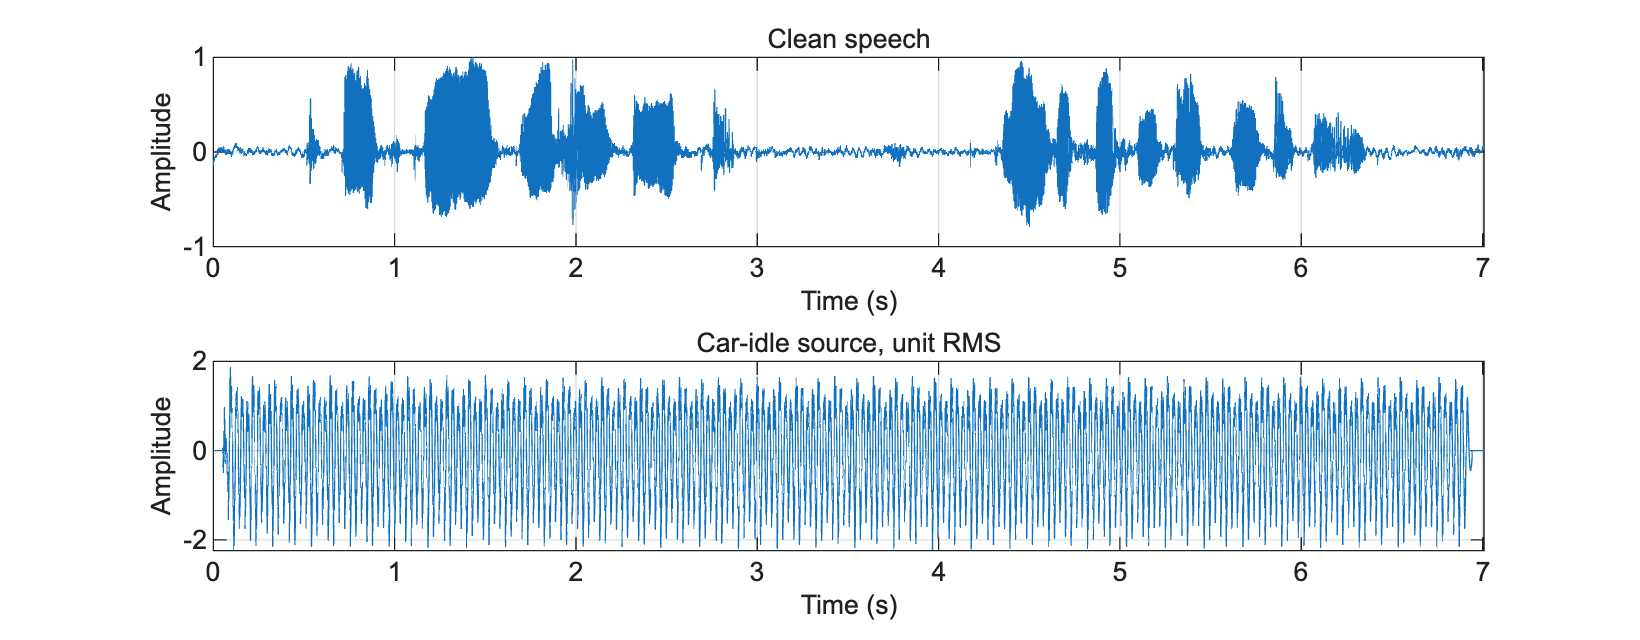

r2_plot_section_01;

Figure 2. Prepared clean speech and car-idle noise.

Figure 2 shows the prepared input signals. Speech is peak-normalized, and the car-idle noise is scaled to unit root-mean-square (RMS) level before mixing. These levels are used to make controlled mixtures and do not represent the original recording levels. The speech waveform contains quieter intervals between speech segments, while the car-idle recording continues throughout the clip.

#### 4.3 Generate Controlled Noisy Speech at Target SNRs

targetSNRs=[0 5 10]; mainIndex=find(targetSNRs==5);
white=randn(N,1); white=white-mean(white);
white=white/sqrt(mean(white.^2));
noiseSources={n,white}; noiseNames=["CarIdle","WhiteGaussian"];
noisySignals=cell(2,numel(targetSNRs)); noiseSignals=noisySignals;
measuredInputSNR=zeros(2,numel(targetSNRs));
for ni=1:2
    for si=1:numel(targetSNRs)
        d=noiseSources{ni}*sqrt(mean(x.^2)/10^(targetSNRs(si)/10));
        noiseSignals{ni,si}=d; noisySignals{ni,si}=x+d;
        measuredInputSNR(ni,si)=10*log10(sum(x.^2)/sum(d.^2));
        assert(abs(measuredInputSNR(ni,si)-targetSNRs(si))<1e-10);
    end
end
yMain=noisySignals{1,mainIndex}; dMain=noiseSignals{1,mainIndex};
inputTable=array2table(measuredInputSNR, ...
    'VariableNames',{'SNR0','SNR5','SNR10'});
inputTable.Noise=noiseNames';

The table below lists the measured input SNRs.

r2_display_table(inputTable,{'Noise','SNR0','SNR5','SNR10'}, ...
    {'Noise','0 dB','5 dB','10 dB'},[0 2 2 2]);

Noise        0 dB  5 dB  10 dB  
Car idle     0.00  5.00  10.00  
White noise  0.00  5.00  10.00  


Both noise sources are scaled from the clean-speech mean-square power. The measured input SNRs match 0, 5 and 10 dB to numerical precision. The car-idle 5 dB mixture is used for detailed examples.

#### 4.4 STFT Parameters

cfg=struct( ...
    'winLength',256, 'hopSize',64, 'nfft',512, ...
    'noisePercentile',20, 'alpha',1.5, 'beta',0.02, ...
    'oracleFloor',0.05, 'initNoiseSeconds',0.25, ...
    'vadSpeechRatio',3.5, 'vadNoiseRatio',1.5, ...
    'floorRiseSeconds',10, 'floorFallSeconds',0.04, ...
    'psdTimeConstant',0.20, ...
    'computeSTOI',exist('stoi','file')==2);
fprintf(['Window %.1f ms; hop %.1f ms; ' ...
    'overlap %.1f%%; FFT spacing %.4f Hz\n'], ...
    1000*cfg.winLength/fs,1000*cfg.hopSize/fs, ...
    100*(1-cfg.hopSize/cfg.winLength),fs/cfg.nfft);

Window 32.0 ms; hop 8.0 ms; overlap 75.0%; FFT spacing 15.6250 Hz


fprintf('STOI available: %d\n',cfg.computeSTOI);

STOI available: 1


At 8 kHz, the window and hop correspond to 32 ms and 8 ms, giving 75% overlap. The 512-point FFT gives a frequency grid spacing of 15.625 Hz; the window length determines the underlying frequency resolution. The main method comparisons keep these settings fixed, with alpha = 1.5 and beta = 0.02.

#### 4.5 Manual STFT Analysis for Main 5 dB Example

% r2_stft contains the explicit window/FFT loop and boundary
% padding.
[Ystft,meta]=r2_stft(yMain,cfg);
Xstft=r2_stft(x,cfg); Dstft=r2_stft(dMain,cfg);
validFrames=meta.fullFrames;
timeFrames=(meta.starts-1-meta.padLeft+cfg.winLength/2)/fs;
freqAxis=(0:cfg.nfft/2)*fs/cfg.nfft;
fprintf('Complete frames: %d\n',sum(validFrames));

Complete frames: 873


The STFT helper applies a Hann window and an FFT to each frame. The main 5 dB mixture contains 873 complete frames without padding. Only these frames are used for noise estimation, so padded boundary samples do not affect the estimate. The clean-speech and exact-noise STFTs are stored separately for comparison and evaluation; they are not supplied to the practical noise estimators.

#### 4.6 Noise PSD Estimation from Low-Energy Frames and VAD

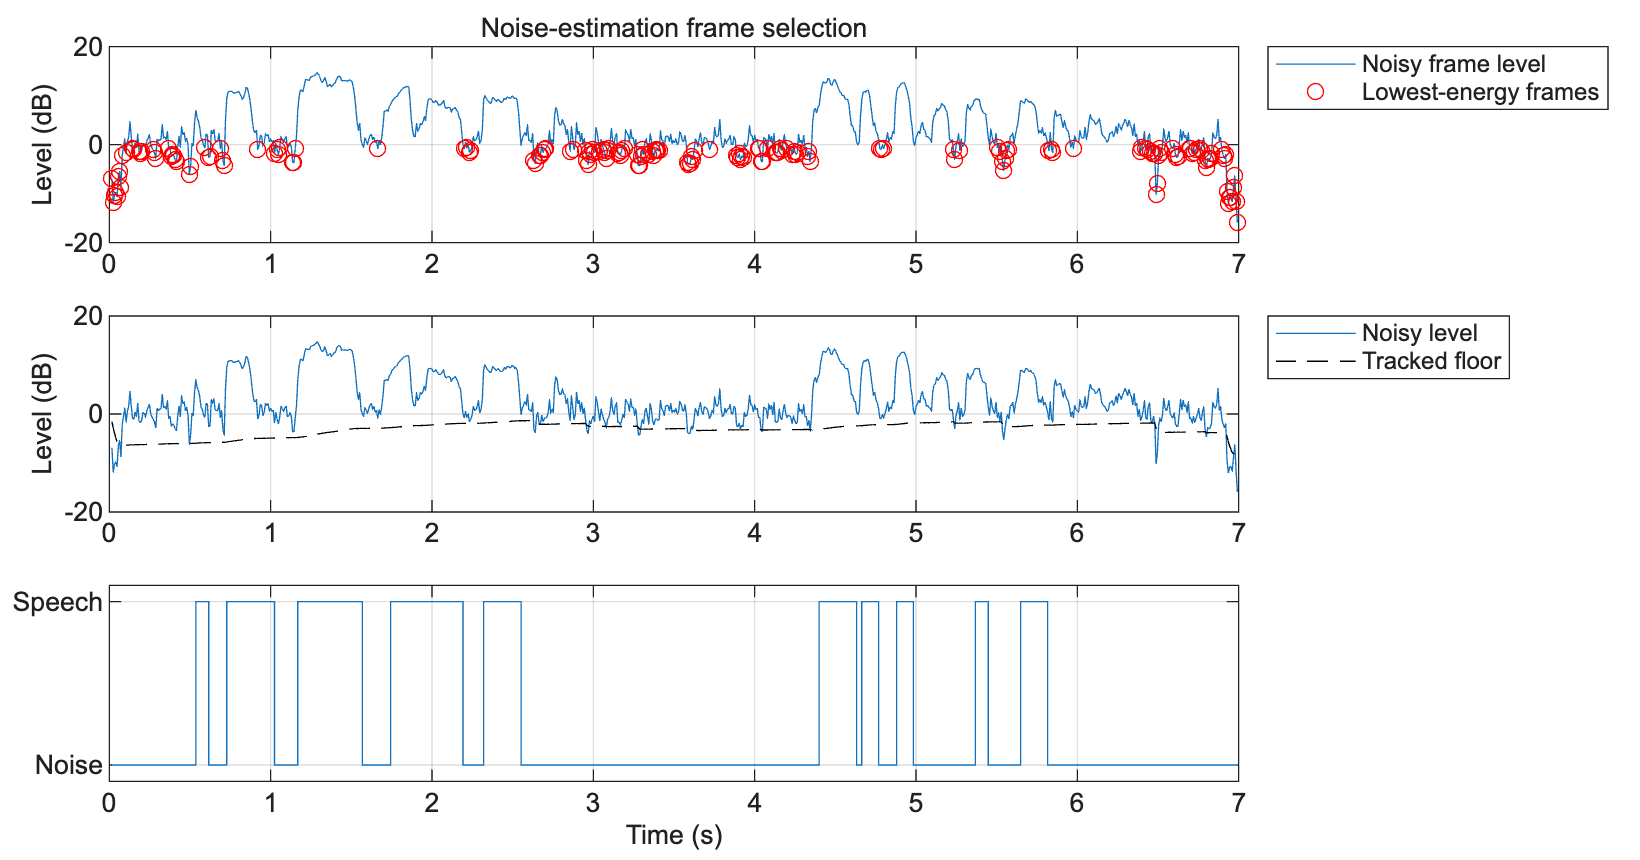

[noisePSD,percentileInfo]=r2_noise_psd(Ystft,meta,fs,cfg, ...
    'percentile');
[vadNoisePSD,vadInfo]=r2_noise_psd(Ystft,meta,fs,cfg,'vad');
% Double-threshold VAD with a hold region and an adaptive noise
% floor.
% The detector uses unweighted spectral frame levels.
r2_plot_section_02;

Figure 3. Percentile frame selection, tracked VAD floor and VAD decisions.

Figure 3 shows how the two methods select frames from the noisy mixture. In the top panel, the percentile method selects frames with lower levels. The middle panel compares the noisy frame level with the tracked VAD floor. The bottom panel shows the resulting speech and noise decisions, including a long noise-labelled interval near the central pause. These labels are estimates; the plot alone does not establish that every selected noise frame is free of speech.

#### 4.7 Practical Spectral Subtraction

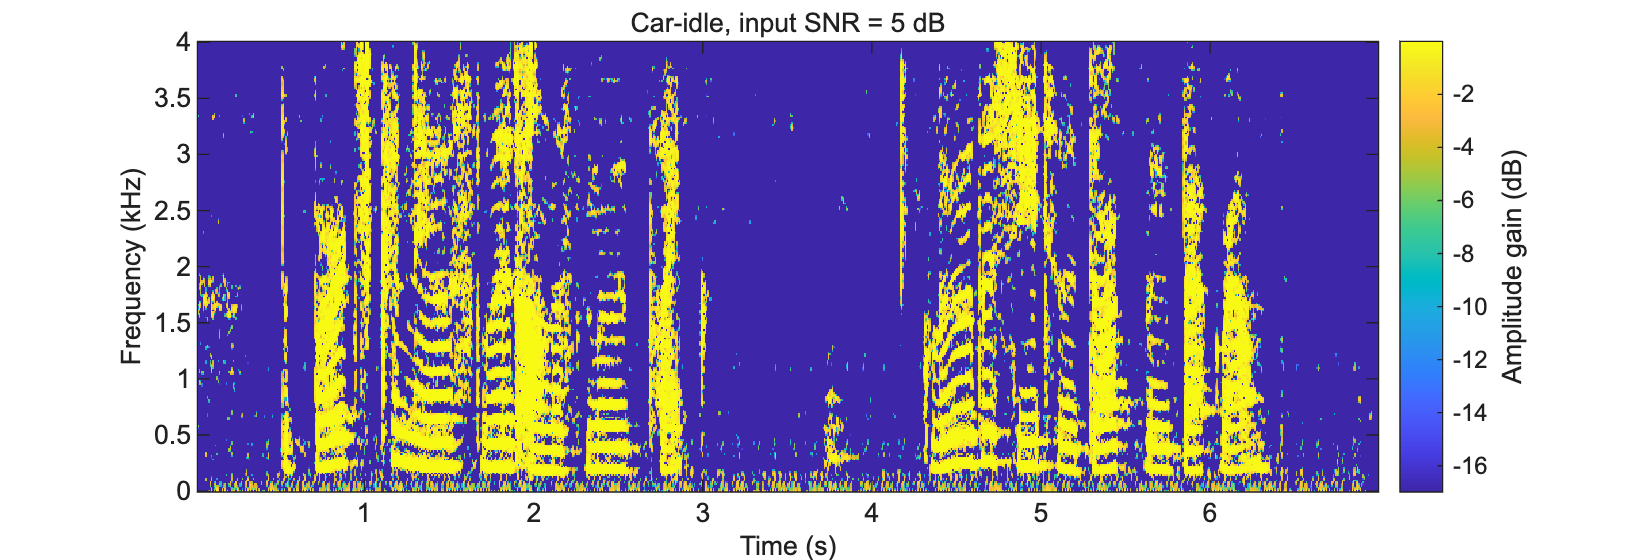

% Exactly the same alpha, beta and gain rule for both practical
% estimators.
gain=r2_spectral_gain(Ystft,noisePSD,cfg);
vadGain=r2_spectral_gain(Ystft,vadNoisePSD,cfg);
EnhancedSTFT=gain.*Ystft;
VADEnhancedSTFT=vadGain.*Ystft;
r2_plot_section_03;

Figure 4. Percentile amplitude gain for the car-idle 5 dB mixture.

Figure 4 shows the percentile gain in decibels. Darker regions have lower gain and receive stronger attenuation. The low-gain regions are clear during the central pause, while many speech-related time-frequency regions receive higher gains. The VAD method uses the same alpha, beta and gain rule, so the practical comparison changes only the noise estimator.

#### 4.8 Inverse STFT and Overlap-Add Reconstruction

% r2_istft contains the explicit IFFT, synthesis window and WOLA
% loop.
enhanced=r2_istft(EnhancedSTFT,meta);
vadEnhanced=r2_istft(VADEnhancedSTFT,meta);
xReconstructed=r2_istft(Xstft,meta);
relativeError=norm(xReconstructed-x)/norm(x);
maxAbsoluteError=max(abs(xReconstructed-x));
assert(relativeError<1e-10, ...
    'Unmodified STFT/ISTFT reconstruction failed.');
reconstructionTable=table(relativeError,maxAbsoluteError);
disp(reconstructionTable);

    relativeError    maxAbsoluteError
    _____________    ________________

     1.7374e-16         4.4409e-16   



writetable(reconstructionTable,fullfile(outputFolder, ...
    'reconstruction_check.csv'));

The unchanged STFT/ISTFT pair reconstructs the signal with a relative error of 1.74 × 10⁻¹⁶. Weighted overlap-add divides by the sum of squared window weights, and trimming removes the padding. This check covers every original sample and confirms that reconstruction error is negligible for the enhancement comparisons.

#### 4.9 SNR, SI-SDR and STOI Evaluation for the Main 5 dB Example

% Reference components below are evaluation only; gains were
% estimated from y.
speechPractical=r2_istft(gain.*Xstft,meta);
noisePractical=r2_istft(gain.*Dstft,meta);
speechVAD=r2_istft(vadGain.*Xstft,meta);
noiseVAD=r2_istft(vadGain.*Dstft,meta);
R0=r2_metrics(x,dMain,yMain,x,dMain,fs,cfg.computeSTOI);
R1=r2_metrics(x,dMain,enhanced,speechPractical,noisePractical,fs, ...
    cfg.computeSTOI);
R2=r2_metrics(x,dMain,vadEnhanced,speechVAD,noiseVAD,fs, ...
    cfg.computeSTOI);
mainMetricTable=vertcat(struct2table(R0),struct2table(R1), ...
    struct2table(R2));
mainMetricTable.Method=["Noisy";"Percentile_SS";"VAD_SS"];

writetable(mainMetricTable,fullfile(outputFolder, ...
    'main_5dB_metrics.csv'));
r2_display_table(mainMetricTable, ...
    {'Method','SNR_dB','SI_SDR_dB','STOI'}, ...
    {'Method','SNR (dB)','SI-SDR (dB)','STOI'},[0 2 2 3]);

Method      SNR (dB)  SI-SDR (dB)  STOI   
Noisy       5.00      5.01         0.889  
Percentile  10.67     10.60        0.892  
VAD         12.69     12.53        0.872  


Table 1. Main car-idle 5 dB results before playback scaling.

Table 1 shows different rankings for SNR and STOI. At car-idle 5 dB, percentile subtraction raises output SNR to 10.67 dB and VAD raises it to 12.69 dB. Their SI-SDR values are 10.60 and 12.53 dB. However, VAD reduces STOI from 0.889 to 0.872, while percentile subtraction gives 0.892. In this example, the larger SNR improvement comes with a lower intelligibility prediction.

#### 4.10 Prepare Audio Comparisons

mainAudio={x,yMain,enhanced,vadEnhanced};
audioNames={'clean','noisy','percentile','vad'};

The four signals are stored in a cell array with matching names. No gain is applied in this step, so their levels remain unchanged.

#### 4.11 Waveform and Spectrogram Comparison

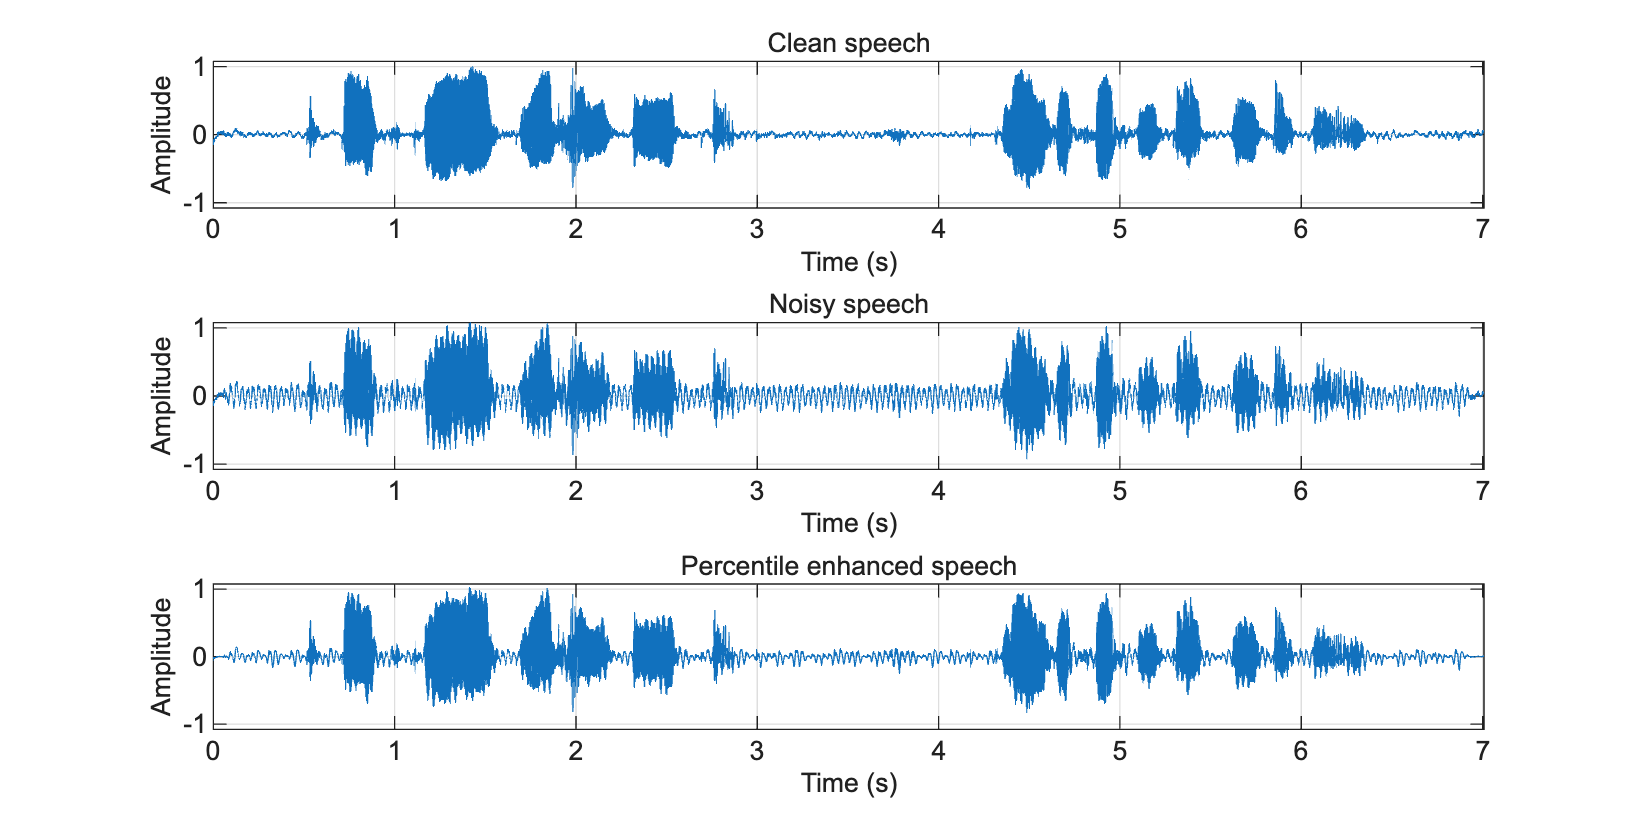

r2_plot_section_04;

Figure 5. Clean, noisy and percentile-enhanced waveforms with common amplitude limits.

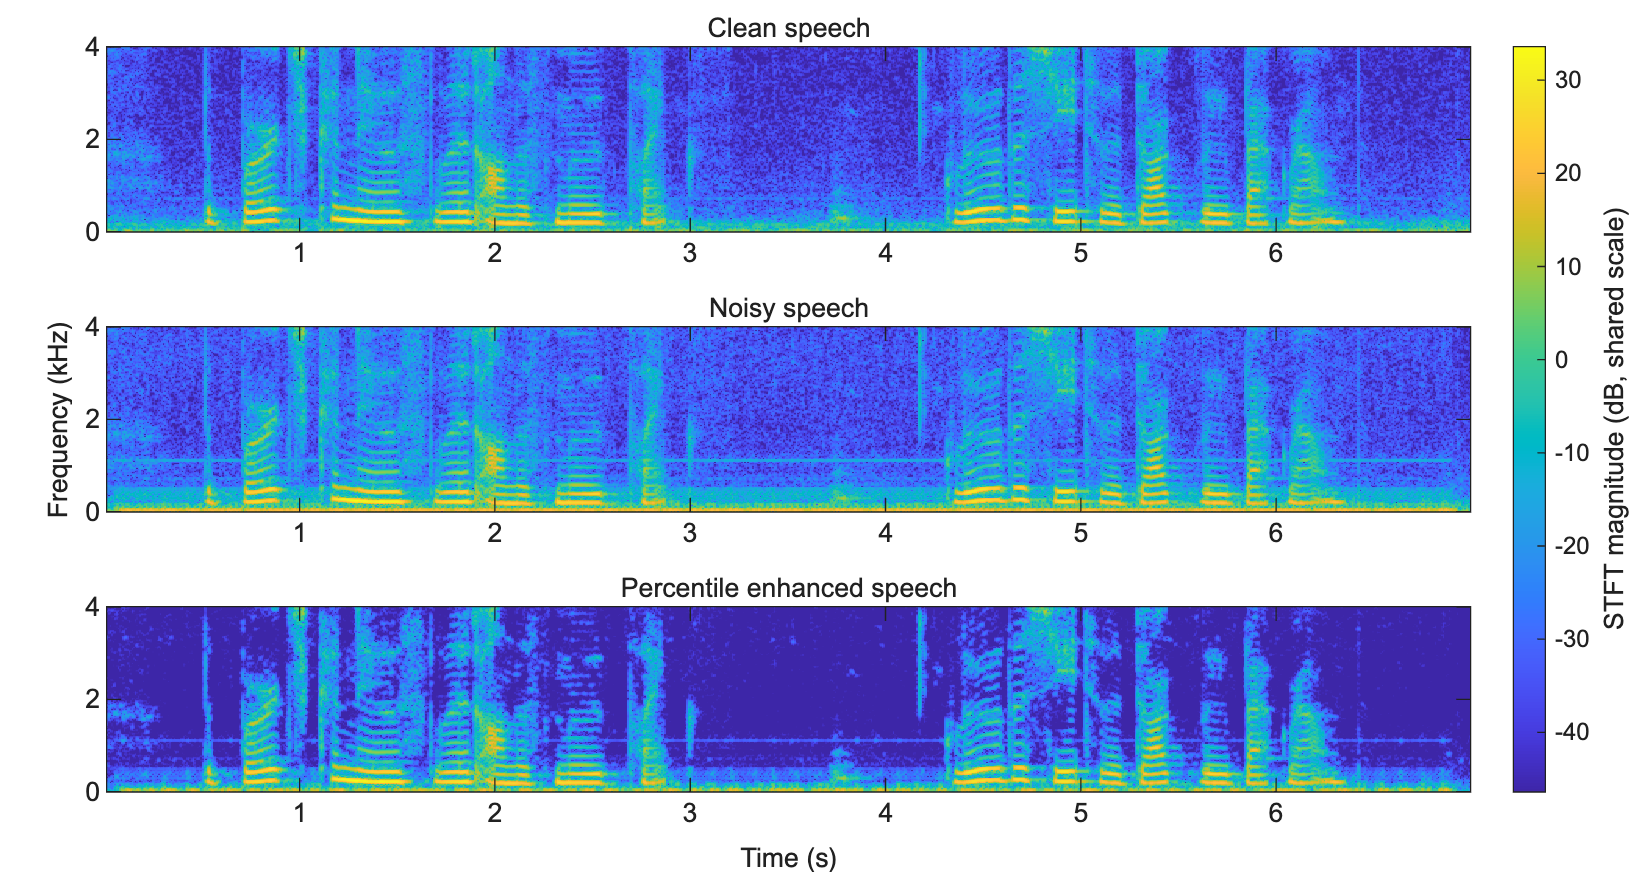

r2_plot_section_09;

Figure 6. Clean, noisy and percentile-enhanced spectrograms with shared colour limits.

Figure 5 shows lower background amplitude during pauses after percentile subtraction. In Figure 6, background energy is reduced, while the main speech bands remain visible. Figure 5 uses common amplitude limits, and Figure 6 uses the same STFT settings and colour limits for each signal. The plots show where the signal changes, while Table 1 gives the numerical comparison.

#### 4.12 Multi-SNR Evaluation

tables={}; bundles=cell(2,numel(targetSNRs));
for ni=1:2
    for si=1:numel(targetSNRs)
% Practical entry points use noisy input only. The helper separately
% computes explicitly labelled references and evaluation
% diagnostics.
        [T,bundles{ni,si}]=r2_evaluate_condition( ...
            x,noiseSignals{ni,si},fs,cfg);
        T.Noise=repmat(noiseNames(ni),height(T),1);
        T.TargetSNR_dB=repmat(targetSNRs(si),height(T),1);
        T.InputSNR_dB=repmat(measuredInputSNR(ni,si),height(T),1);
        T.SNRImprovement_dB=T.SNR_dB-T.InputSNR_dB;
        T.SI_SDRImprovement_dB=T.SI_SDR_dB- ...
            T.SI_SDR_dB(T.Method=="Noisy");
        tables{end+1}=T; %#ok<SAGROW>
    end
end
results=vertcat(tables{:});
pick=results.Method=="Noisy" | results.Method== ...
    "Percentile_SS" | results.Method=="VAD_SS";
displayTable=results(pick, ...
    {'Noise','TargetSNR_dB','Method', ...
    'SNR_dB','SI_SDR_dB','STOI'});
displayTable.Properties.VariableNames= ...
    {'Noise','Input_dB','Method', ...
    'SNR_dB','SI_SDR_dB','STOI'};

writetable(results,fullfile(outputFolder,'main_results.csv'));
diagnostics=results(results.Method=="Percentile_SS" | ...
    results.Method=="VAD_SS", ...
    {'Noise','TargetSNR_dB','Method','NoisePSDMeanAbsError_dB', ...
    'SelectedFrameSpeechToNoise_dB'});
writetable(diagnostics,fullfile(outputFolder, ...
    'noise_estimator_diagnostics.csv'));
r2_display_table(displayTable, ...
    {'Noise','Input_dB','Method','SNR_dB','SI_SDR_dB','STOI'}, ...
    {'Noise','Input (dB)','Method','SNR (dB)', ...
    'SI-SDR (dB)','STOI'}, ...
    [0 2 0 2 2 3]);

Noise        Input (dB)  Method      SNR (dB)  SI-SDR (dB)  STOI   
Car idle     0.00        Noisy       0.00      0.02         0.831  
Car idle     0.00        Percentile  6.27      6.15         0.841  
Car idle     0.00        VAD         8.53      7.95         0.813  
Car idle     5.00        Noisy       5.00      5.01         0.889  
Car idle     5.00        Percentile  10.67     10.60        0.892  
Car idle     5.00        VAD         12.69     12.53        0.872  
Car idle     10.00       Noisy       10.00     10.01        0.933  
Car idle     10.00       Percentile  14.37     14.31        0.930  
Car idle     10.00       VAD         16.98     16.90        0.919  
White noise  0.00        Noisy       0.00      0.01         0.451  
White noise  0.00        Percentile  5.61      5.30         0.463  
White noise  0.00        VAD         3.76      1.40         0.430  
White noise  5.00        Noisy       5.00      5.00         0.526  
White noise  5.00        Percentile  10.30     1

Table 2. Main results across two noise types and three input SNRs.

Table 2 compares the noisy baseline and both practical methods at all three input SNRs. Percentile subtraction gives car-idle output SNRs of 6.27, 10.67 and 14.37 dB. The white-noise values are 5.61, 10.30 and 14.82 dB. These measurements use every sample at the original output level, without least-squares rescaling. Complete results and noise-estimation diagnostics are saved as CSV files.

#### 4.13 Plot Multi-SNR Results

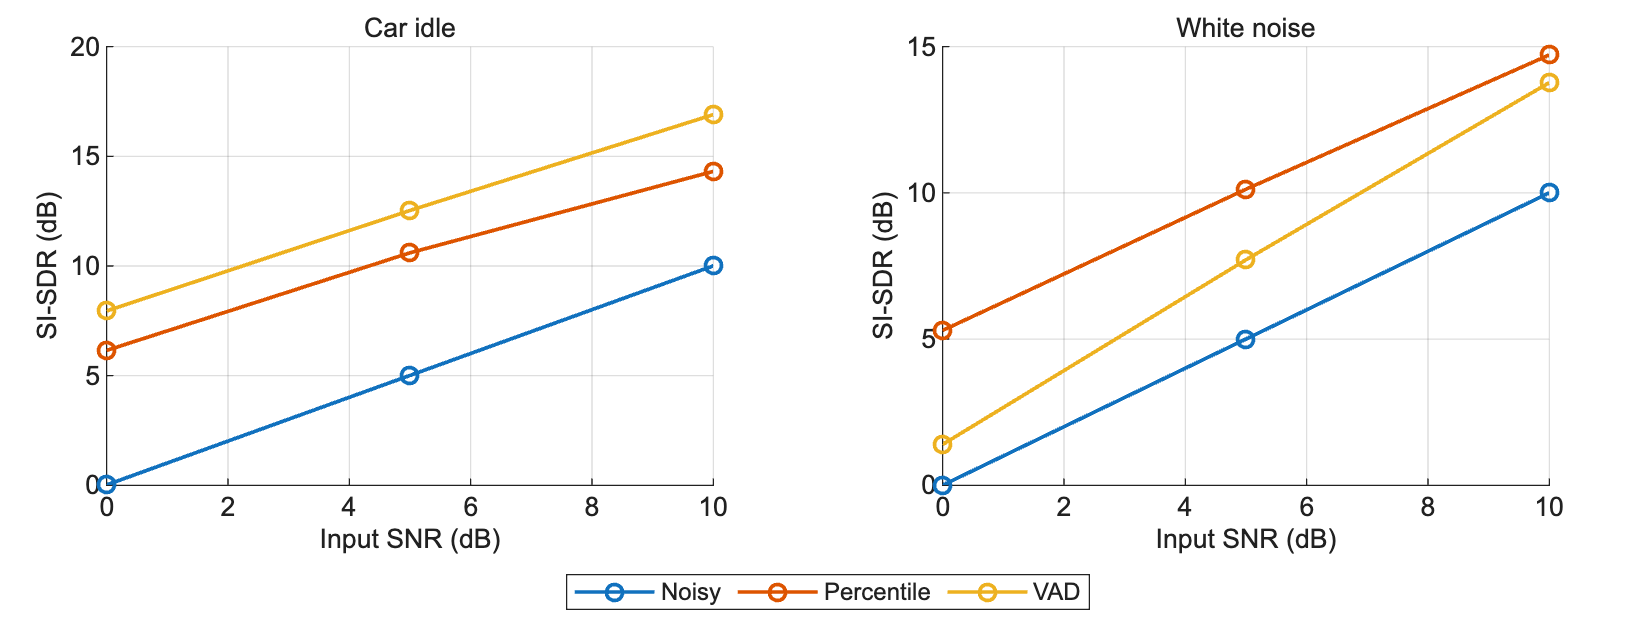

r2_plot_section_05;

Figure 7. SI-SDR across input SNRs for each noise type.

Figure 7 shows that the SI-SDR ranking changes with noise type in the main recording. VAD gives higher SI-SDR than percentile subtraction at all three car-idle SNRs. Percentile subtraction gives higher SI-SDR in all three white-noise cases. At white-noise 5 dB, the values are 10.13 dB for percentile subtraction and 7.71 dB for VAD.

#### 4.14 Oracle and Controlled True-PSD Reference Comparison

B=bundles{1,mainIndex};
oracleEnhanced=B.Oracle_Wiener_reference.out;
truePSDEnhanced=B.TruePSD_SS_reference.out;
referenceTable=results(results.Noise=="CarIdle" & ...
    results.TargetSNR_dB==5,:);

writetable(referenceTable,fullfile(outputFolder, ...
    'reference_comparison_5dB.csv'));
% TruePSD_SS_reference changes only the noise-PSD source in spectral
% subtraction.
% Oracle_Wiener_reference also changes gain law and floor; it is not
% a proven bound.
r2_display_table(referenceTable, ...
    {'Method','SNR_dB','SI_SDR_dB','STOI'}, ...
    {'Method','SNR (dB)','SI-SDR (dB)','STOI'},[0 2 2 3]);

Method      SNR (dB)  SI-SDR (dB)  STOI   
Noisy       5.00      5.01         0.889  
Percentile  10.67     10.60        0.892  
VAD         12.69     12.53        0.872  
True PSD    14.99     14.91        0.909  
Oracle      17.45     17.38        0.967  


Table 3. Practical methods and controlled references at car-idle 5 dB.

The true-PSD reference replaces the estimated noise PSD with the average power spectrum of the known noise, while keeping the spectral-subtraction rule unchanged. In Table 3, it reaches 14.99 dB output SNR, compared with 10.67 dB for percentile subtraction and 12.69 dB for VAD. The oracle Wiener-style reference uses both clean-speech and exact-noise STFTs to calculate its gain and reaches 17.45 dB. Because it also changes the gain rule and floor, its full advantage cannot be attributed to noise estimation alone.

#### 4.15 Plot Practical Methods versus References

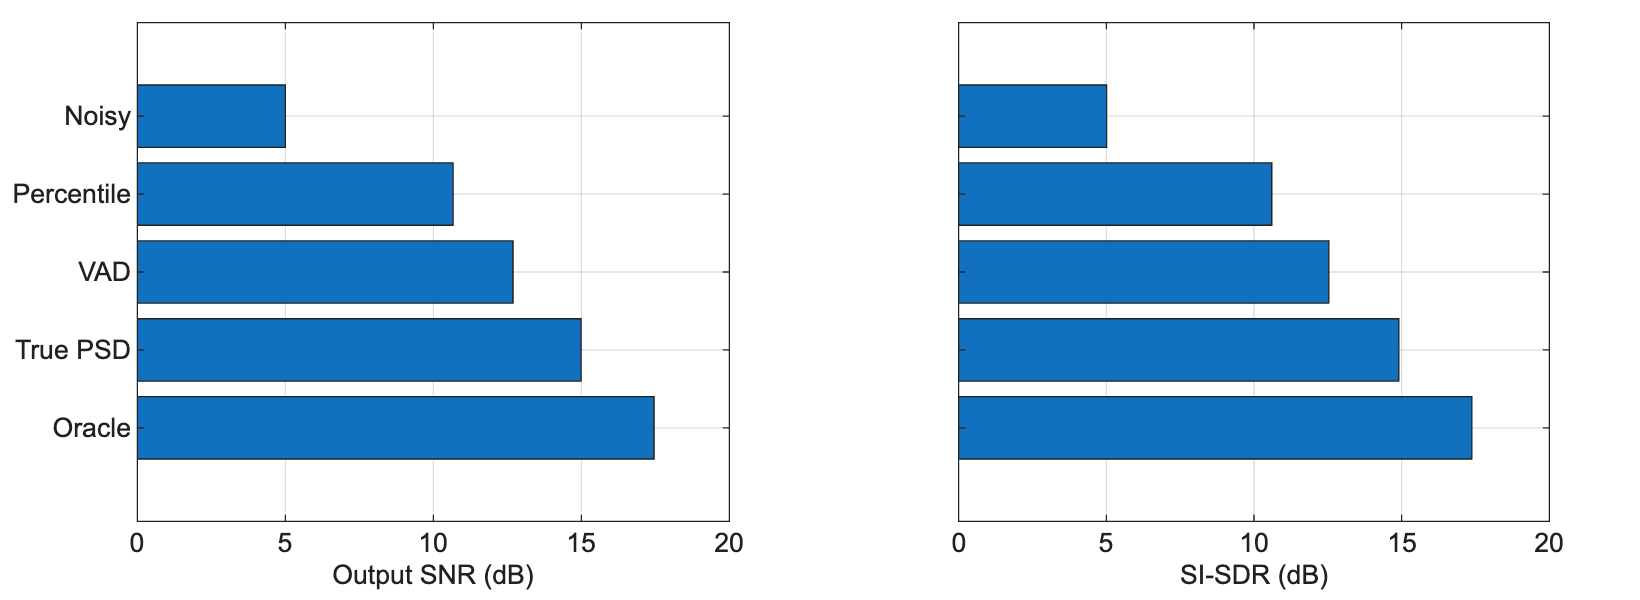

r2_plot_section_06;

Figure 8. Output SNR and SI-SDR for the main reference comparison.

Figure 8 shows the same method ranking for output SNR and SI-SDR in the main 5 dB case. The true-PSD reference gives higher scores than both practical methods, suggesting room to improve noise estimation. However, Table 1 shows that a higher SNR does not always give a higher STOI score.

#### 4.16 Playback and Export with One Common Gain

allAudio=[mainAudio,{oracleEnhanced}];
allAudioNames=[audioNames,{'oracle_reference'}];
sharedPlaybackGain=0.95/max(cellfun(@(v)max(abs(v)),allAudio));
for k=1:numel(allAudio)
    clip=sharedPlaybackGain*allAudio{k};
    audiowrite(fullfile(outputFolder, ...
    [allAudioNames{k} '_car_5dB.wav']),clip,fs);
    if PLAY_AUDIO
        fprintf('Playing %s\n',allAudioNames{k}); sound(clip, ...
    fs); pause(N/fs+0.5);
    end
end

Five WAV files are exported with the same gain: clean, noisy, percentile, VAD and oracle reference. Using one gain preserves their relative levels for listening comparisons. All numerical metrics are calculated before this playback and export scaling. These files support informal listening comparisons; no formal listening test was conducted.

#### 4.17 Spectrogram Comparison Including Oracle

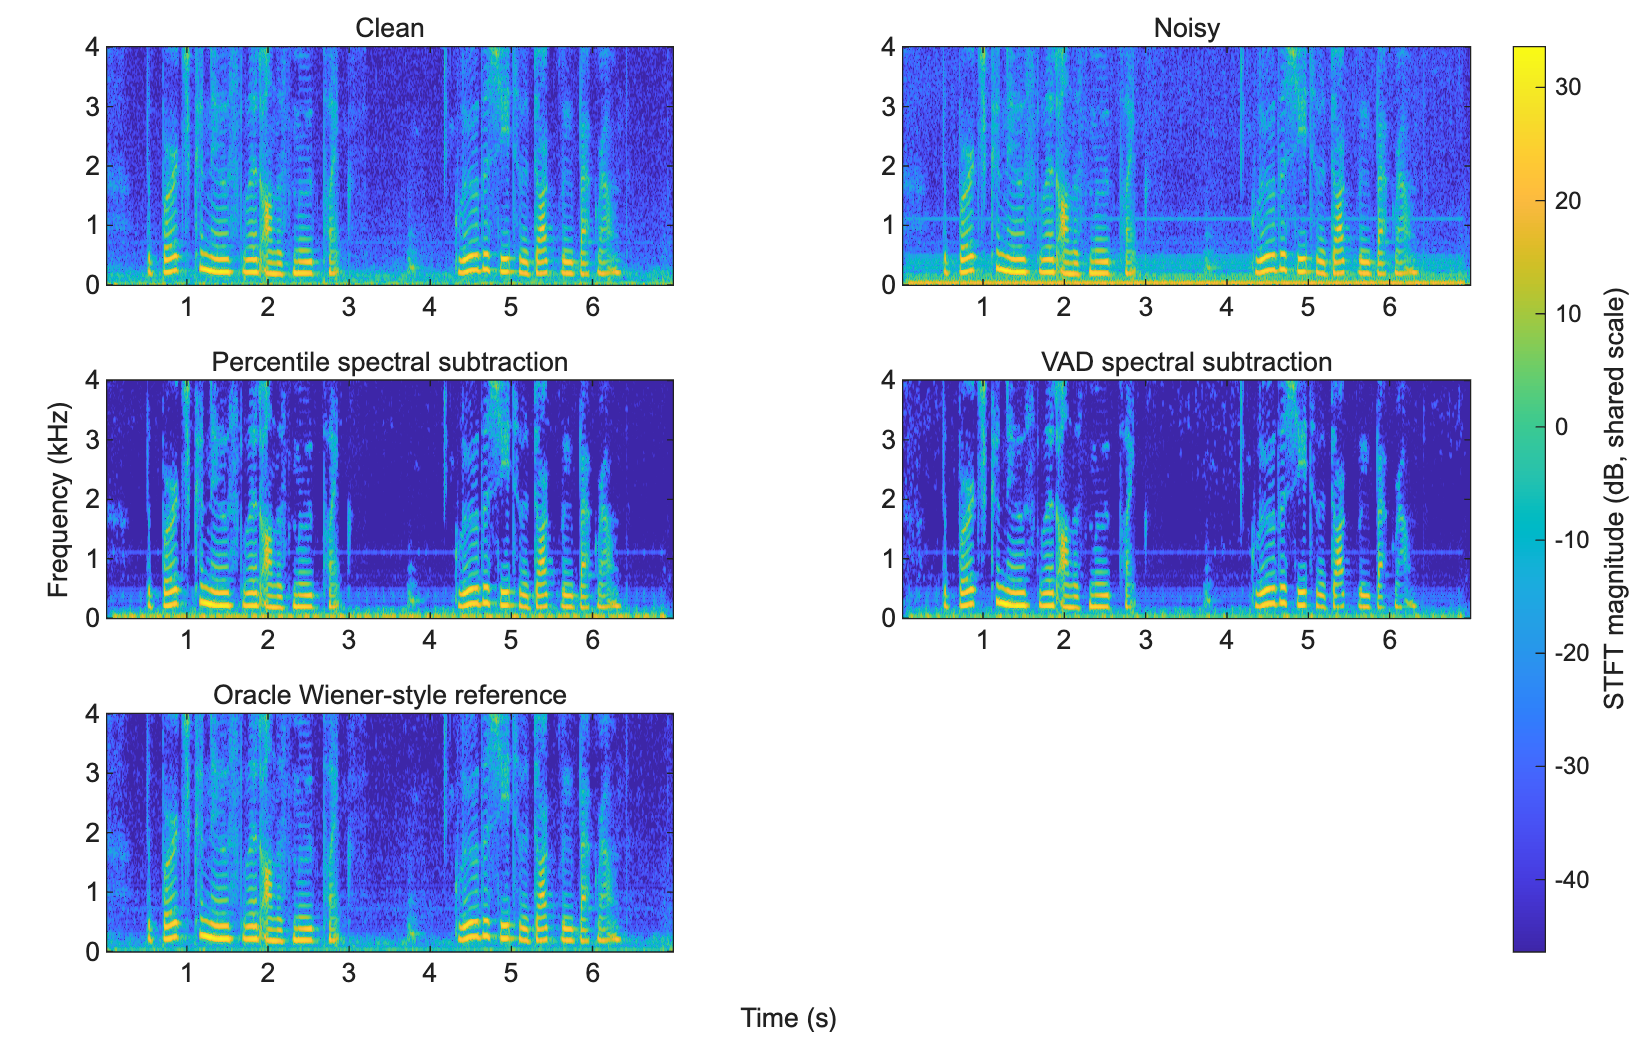

fig=r2_plot_spectra(allAudio, ...
    {'Clean','Noisy','Percentile spectral subtraction', ...
    'VAD spectral subtraction', ...
    'Oracle Wiener-style reference'},fs,cfg, ...
    'Main 5 dB comparison with identical colour limits',2);
r2_save_figure(fig,outputFolder,'figure09_including_oracle');

Figure 9. Spectrograms including VAD and the oracle reference; all panels share colour limits.

Figure 9 adds the VAD and oracle outputs to the comparison in Figure 6. VAD reduces more background energy than percentile subtraction in the main example. The panels use the same colour limits. However, the STOI scores in Table 1 show that stronger background attenuation does not necessarily improve predicted intelligibility.

#### 4.18 Noise Reduction and Speech Preservation

% All gains are frozen from the noisy input before processing X and
% D.
assert(max(results.DecompositionRelativeError)<1e-10, ...
    'Processed components do not sum to the output.');
pick=results.TargetSNR_dB==5 & ...
    (results.Method=="Percentile_SS" | results.Method=="VAD_SS");
preservationTable=results(pick,{'Noise','Method', ...
    'NoiseReduction_dB', ...
    'SpeechRetained_pct','SpeechDistortionSNR_dB','STOI'});


writetable(preservationTable,fullfile(outputFolder, ...
    'speech_noise_decomposition.csv'));
r2_display_table(preservationTable, ...
    {'Noise','Method','NoiseReduction_dB','SpeechRetained_pct', ...
    'SpeechDistortionSNR_dB','STOI'}, ...
    {'Noise','Method','Noise (dB)','Speech (%)','Dist. (dB)', ...
    'STOI'}, ...
    [0 0 2 1 2 3]);

Noise        Method      Noise (dB)  Speech (%)  Dist. (dB)  STOI   
Car idle     Percentile  6.06        97.3        19.99       0.892  
Car idle     VAD         12.19       86.4        14.14       0.872  
White noise  Percentile  5.96        95.6        19.21       0.542  
White noise  VAD         7.74        73.0        10.31       0.522  


Table 4. Frozen-gain decomposition at 5 dB. Noise is attenuation, speech is retained energy, and Dist. is speech-distortion SNR.

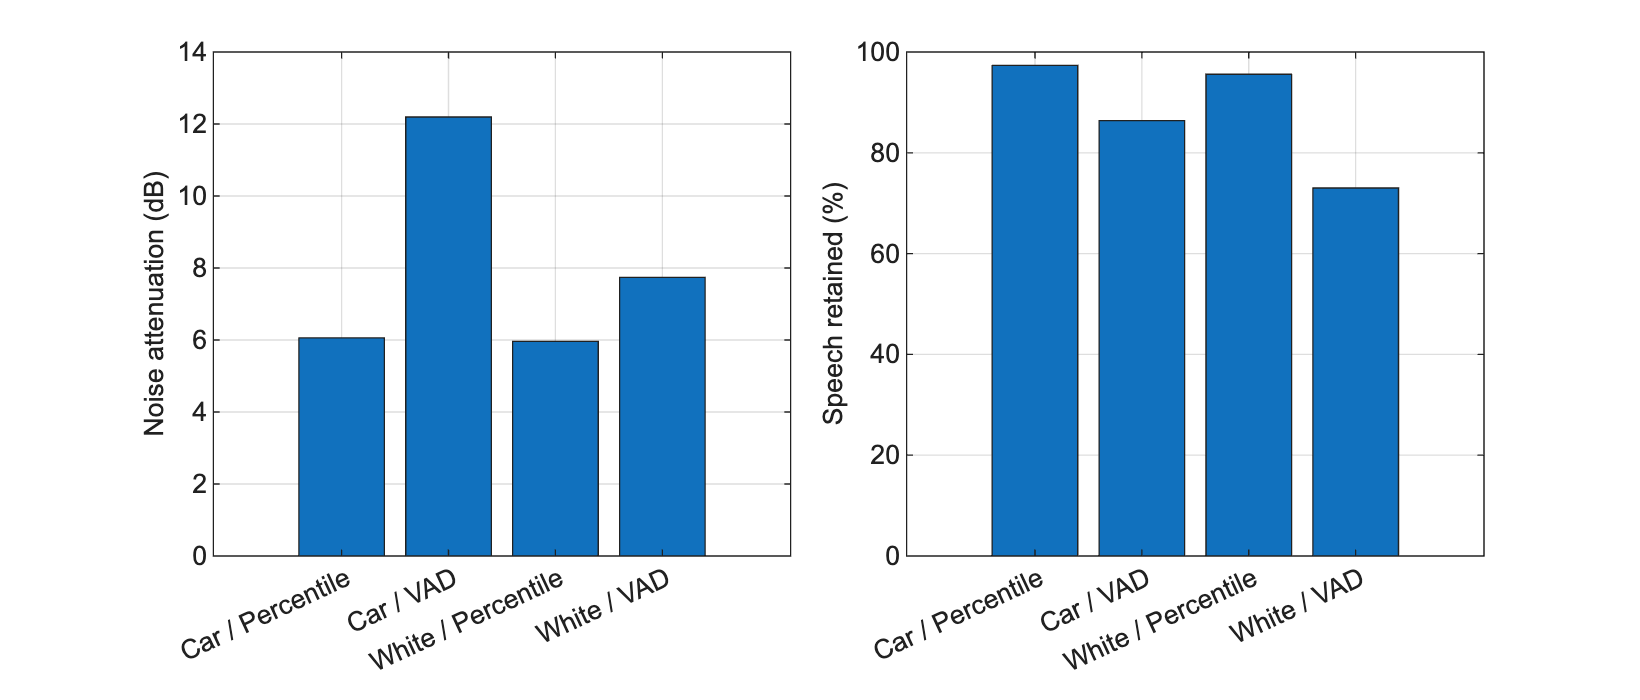

r2_plot_section_07;

Figure 10. Noise attenuation and retained speech energy at 5 dB.

Table 4 and Figure 10 show the balance between noise reduction and speech loss. At car-idle 5 dB, percentile subtraction attenuates noise by 6.06 dB and retains 97.3% of speech energy. VAD attenuates noise by 12.19 dB but retains 86.4%. VAD also gives a lower speech-distortion SNR, 14.14 dB compared with 19.99 dB. This means that its processed clean-speech component differs more from the original. With white noise, speech energy retention is 95.6% for percentile subtraction and 73.0% for VAD. Retained energy does not measure speaker-identity preservation.

#### 4.19 Effect of Suppression Strength

alphaValues=[0.5 1 1.5 2 3]; sweepTables={};
for ni=1:2
    d=noiseSignals{ni,mainIndex}; y=noisySignals{ni,mainIndex};
    [Y,sm]=r2_stft(y,cfg); Xs=r2_stft(x,cfg); Ds=r2_stft(d,cfg);
    [P,~]=r2_noise_psd(Y,sm,fs,cfg,'percentile');
    for ai=1:numel(alphaValues)
        testCfg=cfg; testCfg.alpha=alphaValues(ai);
        G=r2_spectral_gain(Y,P,testCfg);
        z=r2_istft(G.*Y,sm); sx=r2_istft(G.*Xs,sm); dn= ...
    r2_istft(G.*Ds,sm);
        R=r2_metrics(x,d,z,sx,dn,fs,cfg.computeSTOI);
        R.Alpha=alphaValues(ai); R.Noise= ...
    noiseNames(ni); R.InputSNR_dB=5;
        sweepTables{end+1}=struct2table(R); %#ok<SAGROW>
    end
end
alphaSweep=vertcat(sweepTables{:});

writetable(alphaSweep,fullfile(outputFolder,'alpha_sweep.csv'));

save(fullfile(outputFolder,'Report2_code_results.mat'),'cfg', ...
    'fs','x', ...
    'noiseNames', ...
    'targetSNRs','results','alphaSweep','bundles', ...
    'sharedPlaybackGain','relativeError');
r2_display_table(alphaSweep, ...
    {'Noise','Alpha','SNR_dB','STOI','NoiseReduction_dB', ...
    'SpeechRetained_pct'}, ...
    {'Noise','Alpha','SNR (dB)','STOI','Noise (dB)','Speech (%)'}, ...
    [0 1 2 4 2 1]);

Noise        Alpha  SNR (dB)  STOI    Noise (dB)  Speech (%)  
Car idle     0.5    6.45      0.8829  1.59        98.6        
Car idle     1.0    8.37      0.8877  3.61        97.9        
Car idle     1.5    10.67     0.8921  6.06        97.3        
Car idle     2.0    13.04     0.8934  8.82        96.9        
Car idle     3.0    15.70     0.8903  13.29       96.4        
White noise  0.5    6.93      0.5326  2.09        97.8        
White noise  1.0    8.75      0.5387  4.10        96.6        
White noise  1.5    10.30     0.5419  5.96        95.6        
White noise  2.0    11.53     0.5443  7.65        94.8        
White noise  3.0    13.02     0.5457  10.38       93.4        


Table 5. Percentile suppression-strength sweep at 5 dB.

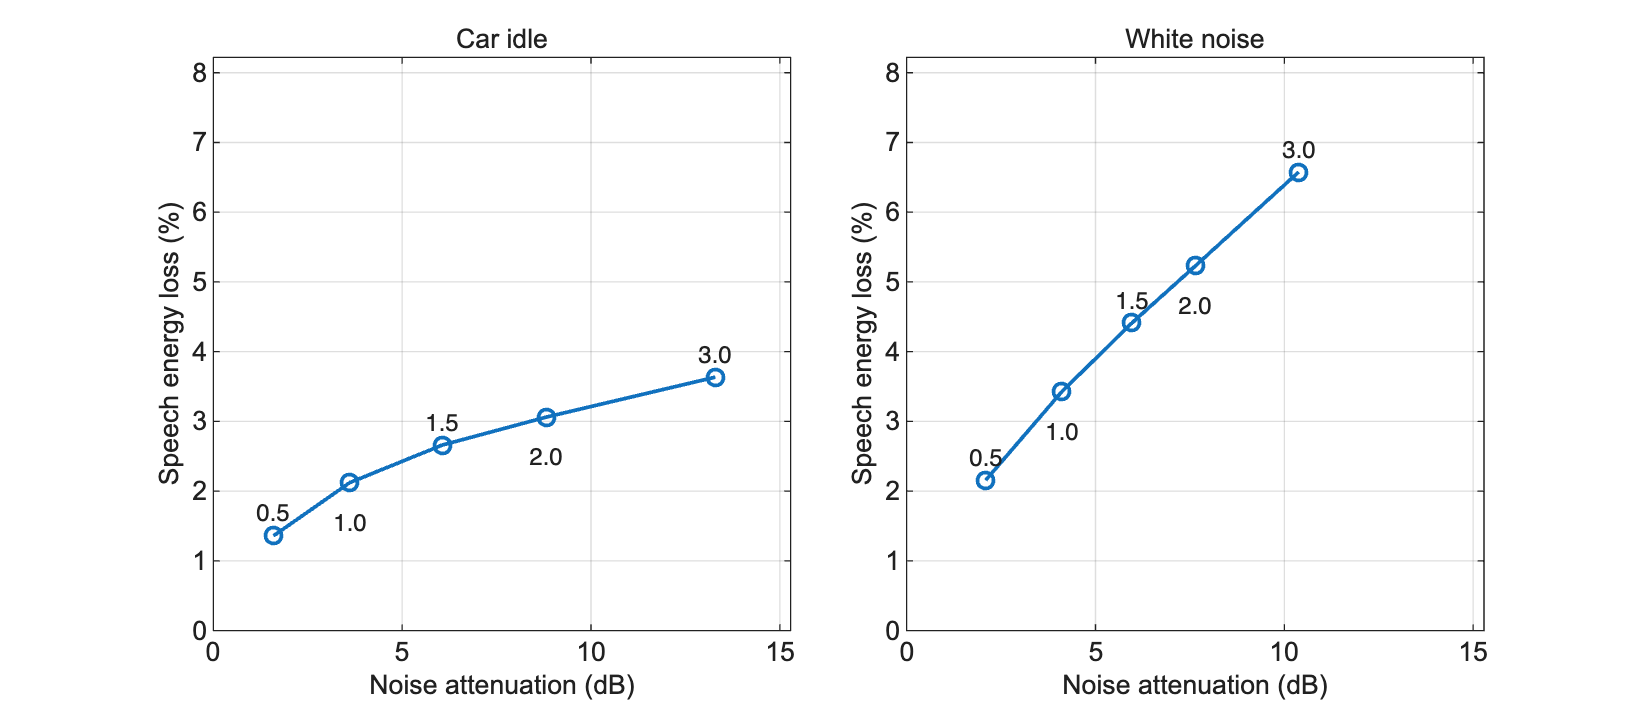

r2_plot_section_08;

Figure 11. Noise attenuation and speech energy loss as alpha changes. Point labels give alpha; both panels use the same axis limits.

Figure 11 shows the effect of increasing alpha while keeping beta = 0.02 and the percentile PSD fixed. For car-idle noise, increasing alpha from 0.5 to 3 raises noise attenuation from 1.59 to 13.29 dB. Speech energy loss also rises, from 1.36% to 3.64%. Table 5 shows that STOI reaches 0.8934 at alpha = 2, then falls to 0.8903 at alpha = 3 despite the higher output SNR. White noise shows a different trend. STOI increases from 0.5326 at alpha = 0.5 to 0.5457 at alpha = 3. The effect of increasing alpha therefore depends on the noise condition. These tests do not identify a generally optimal alpha.

#### 4.20 Prepare the Additional Speech and Noise Recordings

[validationSpeech,validationNoise,validationManifest]= ...
    r2_validation_prepare(scriptFolder,fs);
writetable(validationManifest,fullfile(outputFolder, ...
    'validation_inputs.csv'));
inputColumns={'SpeakerID','UtteranceID','UsedDuration_s'};
disp(validationManifest(:,inputColumns));

    SpeakerID       UtteranceID        UsedDuration_s
    _________    __________________    ______________

      6930       "6930-75918-0001"           5       
      1320       "1320-122617-0001"          5       
      5639       "5639-40744-0000"           5       



The additional speech recordings are LibriSpeech test-clean utterances 6930-75918-0001, 1320-122617-0001 and 5639-40744-0000, from three different speakers. Selection used metadata before enhancement: the first utterance with at least 180 transcript characters for each of the first three distinct speaker IDs in dataset rows 0–199. All three recordings exceed 5 s. The first 5 s of each recording is converted to mono, resampled to 8 kHz, mean-centred and peak-normalised.

Environmental noise uses the first 5 s of the car-idle recording and the 5 s ESC-50 rain clip 1-17367-A-10, originally recorded by cognito perceptu on Freesound (ID 17367). Rain is resampled from 44.1 kHz to 8 kHz. No noise-only prefix is added, so the VAD's assumption of mainly noise during initialization may not hold for these speech clips.

#### 4.21 Validation across Speakers, Noise Types and Random Seeds

validationResults=r2_validation_run( ...
    validationSpeech,validationNoise,validationManifest,fs,cfg);
writetable(validationResults,fullfile(outputFolder, ...
    'validation_all_results.csv'));
mixtureKeys={'SpeakerID','Noise','InputSNR_dB','Seed'};
nSpeakers=numel(unique(validationResults.SpeakerID));
nMixtures=height(unique(validationResults(:,mixtureKeys)));
nResults=height(validationResults);
fprintf('Speakers: %d; mixtures: %d; results: %d\n', ...
    nSpeakers,nMixtures,nResults);

Speakers: 3; mixtures: 45; results: 135


Each speaker is mixed with car-idle noise, rain and white noise at 0, 5 and 10 dB. White-noise seeds 5305, 5306 and 5307 generate three sequences. Each sequence is shared across speakers and scaled to the target SNR. The experiment contains 18 environmental-noise mixtures and 27 white-noise mixtures. Evaluating the noisy baseline and two practical methods gives 135 result rows from 45 mixtures.

All algorithm settings remain fixed, and the additional recordings are not used to tune them. The practical estimators receive noisy speech only. Clean speech and exact noise are used for the metrics and component decomposition.

#### 4.22 Summary of the Additional Validation

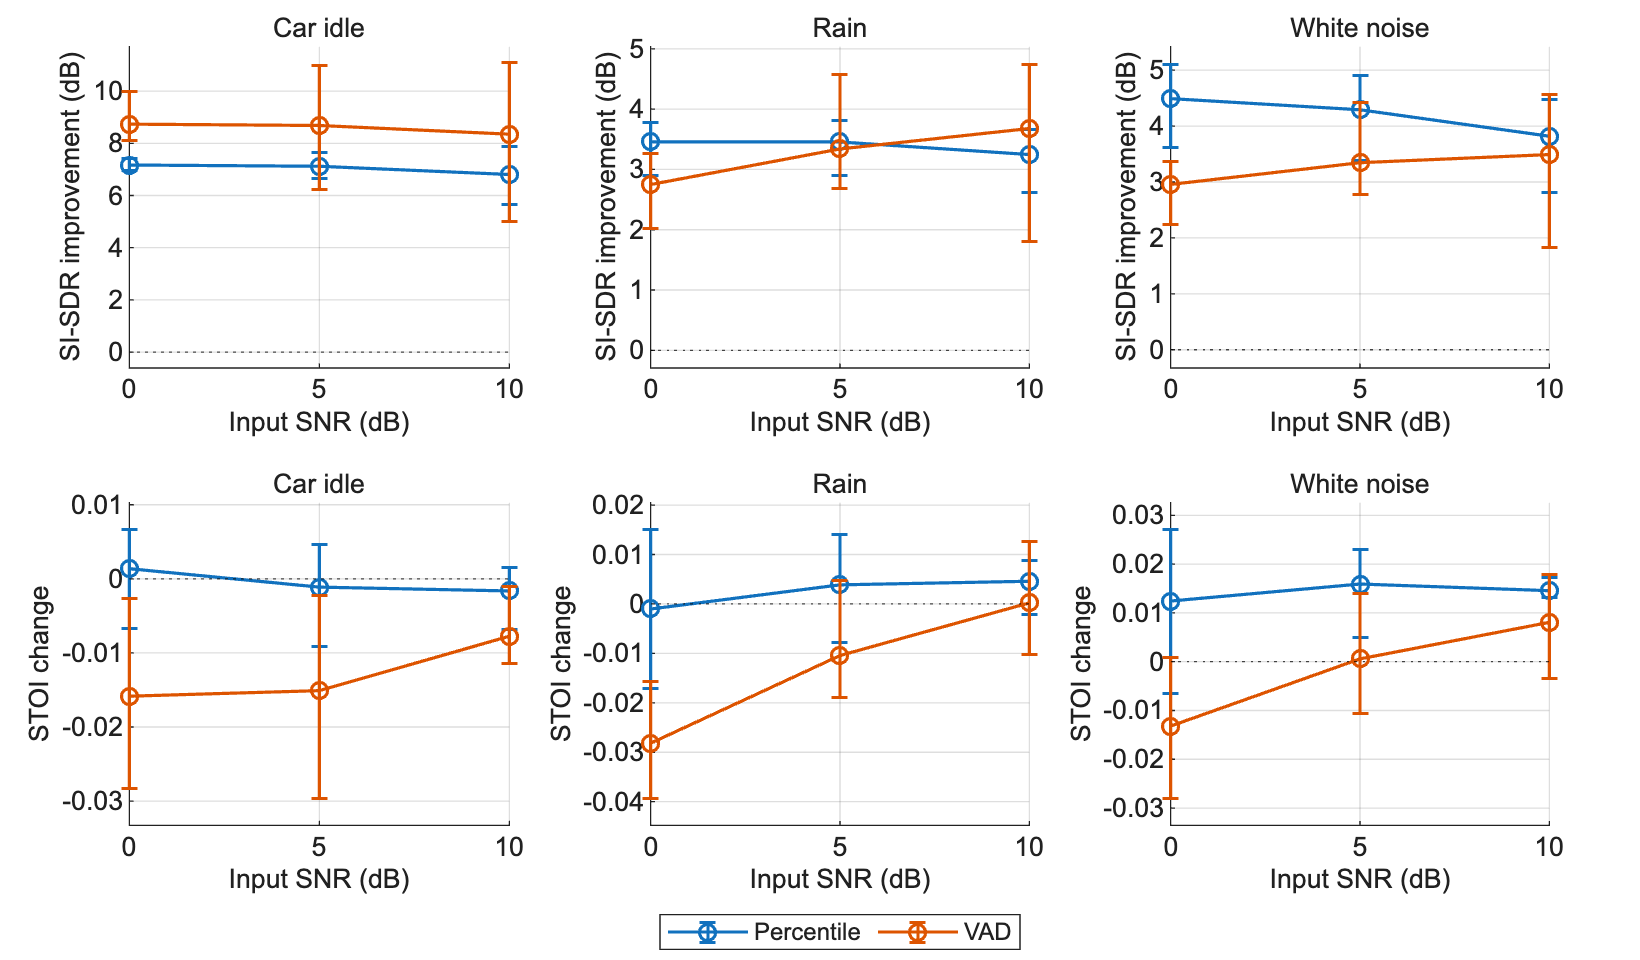

[S,P,Q,fig]=r2_validation_summary(validationResults);
writetable(S,fullfile(outputFolder,'validation_summary.csv'));
writetable(P,fullfile(outputFolder,'validation_per_speaker.csv'));
writetable(Q,fullfile(outputFolder,'validation_by_seed.csv'));
r2_save_figure(fig,outputFolder,'figure12_validation');

Figure 12. Additional-validation means with minimum-to-maximum speaker ranges.

validationTable=S(S.Input_dB==5,{'Noise','Method', ...
    'SI_Gain_dB_Mean','STOI_Change_Mean','SpeechLoss_pct_Mean'});
validationTable.Properties.VariableNames= ...
    {'Noise','Method','SI_Gain_dB','STOI_Change','SpeechLoss_pct'};
r2_display_table(validationTable, ...
    {'Noise','Method','SI_Gain_dB','STOI_Change','SpeechLoss_pct'}, ...
    {'Noise','Method','SI gain (dB)','STOI change', ...
    'Speech loss (%)'}, ...
    [0 0 2 4 1]);

Noise        Method      SI gain (dB)  STOI change  Speech loss (%)  
Car idle     Percentile  7.12          -0.0011      3.1              
Car idle     VAD         8.68          -0.0151      12.1             
Rain         Percentile  3.46          0.0039       6.6              
Rain         VAD         3.34          -0.0104      24.5             
White noise  Percentile  4.29          0.0159       8.4              
White noise  VAD         3.35          0.0006       28.8             


Table 6. Mean validation results at 5 dB. White-noise seeds are averaged within each speaker first.

Figure 12 plots SI-SDR improvement and STOI change relative to noisy speech. White-noise seeds are averaged within each speaker before averaging the three speakers. Error bars show the minimum and maximum speaker values, not confidence intervals. Table 6 gives the mean 5 dB results; the CSV files contain the complete results and seed comparisons.

At 5 dB, percentile subtraction and VAD give mean SI-SDR improvements of 7.12 and 8.68 dB with car-idle noise, 3.46 and 3.34 dB with rain, and 4.29 and 3.35 dB with white noise. VAD has the larger mean only for car-idle noise at this SNR. VAD also loses more speech energy: 12.1% versus 3.1% for car-idle noise, 24.5% versus 6.6% for rain, and 28.8% versus 8.4% for white noise. For rain, the mean SI-SDR improvements differ by 0.12 dB, while the speech energy losses are much further apart.

The mean STOI changes depend on the noise. At car-idle 5 dB, they are −0.0011 for percentile subtraction and −0.0151 for VAD. With white noise, they are +0.0159 and +0.0006. Across the three white-noise seeds, mean SI-SDR improvement ranges from 4.26 to 4.31 dB for percentile subtraction and from 3.26 to 3.41 dB for VAD. Percentile subtraction keeps the higher mean for each tested seed.

#### 4.23 Noise-Frame Diagnostics and Metric Agreement

[frameDiagnostics,metricPairs]= ...
    r2_metric_agreement(validationResults);
writetable(frameDiagnostics, ...
    fullfile(outputFolder,'validation_frame_diagnostics.csv'));
writetable(metricPairs, ...
    fullfile(outputFolder,'metric_agreement.csv'));
r2_display_table(frameDiagnostics, ...
    {'Noise','Method','SelectedRatio_dB','SpeechLoss_pct'}, ...
    {'Noise','Method','Selected X/D (dB)','Speech loss (%)'}, ...
    [0 0 2 1]);

Noise        Method      Selected X/D (dB)  Speech loss (%)  
Car idle     Percentile  -10.93             3.1              
Car idle     VAD         -2.85              12.1             
Rain         Percentile  -12.62             6.6              
Rain         VAD         -0.03              24.5             
White noise  Percentile  -14.48             8.4              
White noise  VAD         1.07               28.8             


Table 7. Mean selected-frame speech-to-noise energy ratio and speech loss at 5 dB. Seeds are averaged within speaker before averaging speakers.

Table 7 shows more speech relative to noise in the frames selected by VAD. The main car-idle example has the same pattern: VAD selects 605 of 873 complete frames, compared with 175 for the percentile method. Their selected-frame clean-speech-to-noise STFT energy ratios are −2.84 and −8.42 dB. These are reference-based diagnostics, not information supplied to the estimators.

VAD-selected frames contain more speech relative to noise. This supports speech contamination in the noise estimate as one explanation for the greater speech energy loss. However, the ratio combines all selected frames, while the VAD gives them different weights when updating the PSD. It therefore does not show that noise power is overestimated at every frequency or separate initialization errors from later frame decisions.

r2_print_diagnostics(percentileInfo,vadInfo,validFrames, ...
    Xstft,Dstft,metricPairs);

Percentile: 175/873 frames; selected X/D -8.42 dB
VAD: 605/873 frames; selected X/D -2.84 dB
Percentile SI-SDR wins: 31/45; STOI wins: 40/45
Different method rankings: 9/45


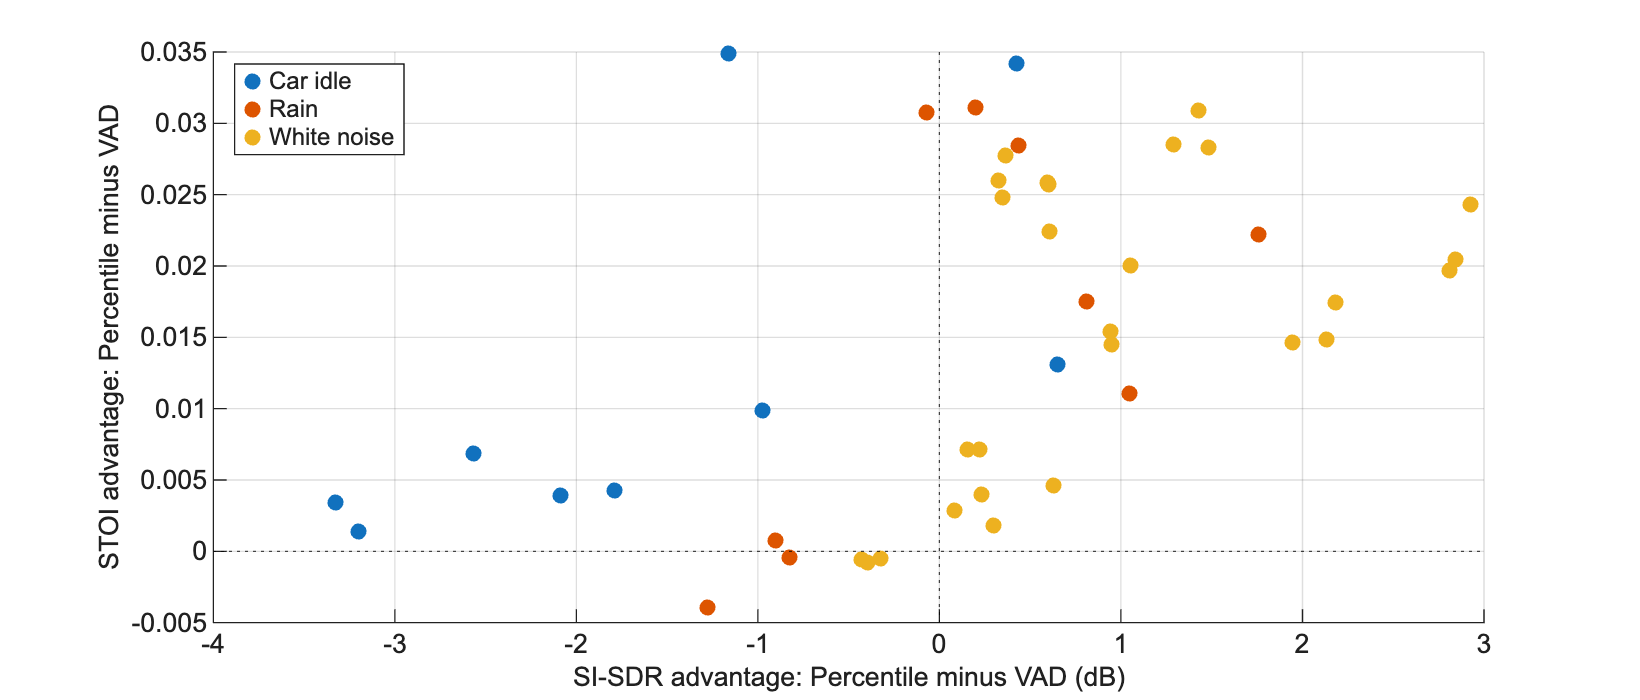

fig=r2_plot_agreement(metricPairs);
r2_save_figure(fig,outputFolder,'figure13_metric_agreement');

Figure 13. Paired method differences across 45 mixtures. Positive values favour percentile subtraction. Points in the upper-left quadrant indicate different rankings for SI-SDR and STOI.

Percentile subtraction gives the larger SI-SDR improvement in 31 of 45 mixtures and the larger STOI change in 40. The metrics rank the methods differently in 9 cases: VAD gives higher SI-SDR, while percentile subtraction gives higher STOI. Figure 13 compares the same mixture for each pair. These findings support using both metrics for this set of recordings; neither measures speaker-identity preservation.

### 5. Discussion

The results show that stronger noise suppression can also change speech. At car-idle 5 dB, VAD removes more noise but retains less speech energy and lowers STOI (Table 4 and Figure 10). The selected-frame measurements show more speech relative to noise in VAD-labelled noise frames (Table 7). This supports speech contamination as a contributor to speech loss. However, initialization, later frame decisions and PSD smoothing were not tested separately.

The true-PSD reference gives approximately 4.3 dB more output SNR than percentile subtraction with the same gain rule (Table 3). This comparison shows the effect of replacing the estimated noise PSD in the main example. The oracle uses clean-speech information and a different gain rule, so its full advantage cannot be attributed to PSD estimation alone. In the car-idle alpha sweep, increasing alpha from 2 to 3 raises SNR but lowers STOI (Table 5). Figure 11 shows the increase in speech energy loss.

The metric comparison gives another reason to assess more than noise suppression. SI-SDR and STOI rank the practical methods differently in 9 of 45 mixtures (Figure 13). In these cases, VAD gives higher SI-SDR, while percentile subtraction gives higher STOI. This is a descriptive result for the tested mixtures; repeated seeds and SNRs do not create independent speech recordings.

Each speaker contributes one utterance, and each environmental noise uses one clip. The comparisons therefore combine differences in speaker, speech content and style. The three white-noise seeds test sequence variation within this set. STOI and retained energy do not establish speaker-identity preservation. That question requires separate enrollment and test utterances in the final project.

### 6. Conclusion

This report compared two noise estimators using the same STFT spectral-subtraction method. Both improved SNR in the main tests, but their SI-SDR ranking depended on the noise type. In the additional 5 dB tests, VAD gave a larger mean SI-SDR improvement for car-idle noise, while percentile subtraction gave a larger improvement for white noise. The mean improvements for rain were close, at 3.46 and 3.34 dB. VAD also caused more speech energy loss in all three conditions. The frame analysis found more speech relative to noise in VAD-selected frames, which helps explain this loss. SI-SDR and STOI ranked the methods differently in 9 of 45 mixtures. These results support assessing noise reduction, speech distortion and predicted intelligibility together. The methods provide a baseline for the final project, where speaker-identity preservation will be tested separately.

### 7. References

[1] S. F. Boll, “Suppression of acoustic noise in speech using spectral subtraction,” IEEE Transactions on Acoustics, Speech, and Signal Processing, vol. 27, no. 2, pp. 113–120, 1979. doi: 10.1109/TASSP.1979.1163209.

[2] J. Le Roux, S. Wisdom, H. Erdogan, and J. R. Hershey, “SDR – half-baked or well done?” arXiv:1811.02508, 2018. https://arxiv.org/abs/1811.02508

[3] C. H. Taal, R. C. Hendriks, R. Heusdens, and J. Jensen, “An algorithm for intelligibility prediction of time-frequency weighted noisy speech,” IEEE Transactions on Audio, Speech, and Language Processing, vol. 19, no. 7, pp. 2125–2136, 2011. doi: 10.1109/TASL.2011.2114881.

[4] MathWorks, “stoi: Short-time objective intelligibility measure,” Audio Toolbox documentation. https://www.mathworks.com/help/audio/ref/stoi.html.

[5] Open Speech Repository, “American English speech files.” https://www.voiptroubleshooter.com/open_speech/american.html. Recording:

OSR_us_000_0010_8k.wav.

[6] OpenSLR, “LibriSpeech ASR corpus,” SLR12, test-clean subset, CC BY 4.0. https://www.openslr.org/12.

[7] K. J. Piczak, “ESC-50: Dataset for environmental sound classification.” https://github.com/karolpiczak/ESC-50 (accessed 29 October 2026). Rain clip: 1-17367-A-10.wav; original recording by cognito perceptu, Freesound ID 17367 (CC0), included in the ESC-10 subset (CC BY 3.0).